# Visualize and Analyze Molecular Structures

### Introduction

This simple example demonstrates how [Python-MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html) can work together for molecular structure visualization. Using a single molecule input, we are illustrating how to process [SMILES](https://en.wikipedia.org/wiki/Simplified_molecular-input_line-entry_system) database and visualize it in MATLAB. 

### Requirements

- [Python](https://www.python.org/)

- [RDKit](https://www.rdkit.org/) Open-Source Cheminformatics Software

- [Bioinformatics](https://www.mathworks.com/products/bioinfo.html) toolbox

#### Install Python 

Set up your Python environment by following the instructions provided in the guide found at [Python](https://www.python.org/downloads/release/python-3110/) webpage. Make sure to give the python address and to check versions of Python compatible with MATLAB products by release. This allows to build proper [MATLAB Interface to Python](https://www.mathworks.com/support/requirements/python-compatibility.html). 

% Set path to Python.exe
pythonExecutable = 'C:\Users\...\AppData\Local\Programs\Python\Python311/python.exe'; % Update this path

% Set the Python.exe in MATLAB
pyenv('Version', pythonExecutable);

% Verify Python config
disp('Python version:');

Python version:


pyversion;


       version: '3.11'
    executable: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311\python.exe'
       library: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311\python311.dll'
          home: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311'
      isloaded: 0



#### Install RDKit

This example uses some of the functions from RDKit. It can be installed easily by following its [installation](https://www.rdkit.org/docs/Install.html) instructions on Linux, Windows, and macOS. You can install RDKit using pip.

#### Add Bioinformatics toolbox

The Bioinformatics Toolbox in MATLAB is specifically required for the 3D visualization of protein structures using the `molviewer` function. If you do not have this toolbox, you can simply install it by

- Click on "Add-Ons" and select "Get Add-Ons" from the dropdown menu.

- In the Add-On Explorer, type "Bioinformatics Toolbox" in the search bar.

- Select the Bioinformatics Toolbox from the search results.

- Click the "Add" or "Install" button to begin the installation process.

- Follow the prompts to complete the installation.

If you don't add this toolbox, you can still run the rest of your code without issues by simply commenting out the line `molviewer(pdbID);`. To do this, add a "%" symbol at the beginning of the line.

### Draw D-Glucose and Luseogliflozin

Simply call the utility function "visualizeMolecule" to visualize a given SMILES structure and store the image in a file. You can get these SMILES strings from public data banks like [PubChem](https://pubchem.ncbi.nlm.nih.gov/).

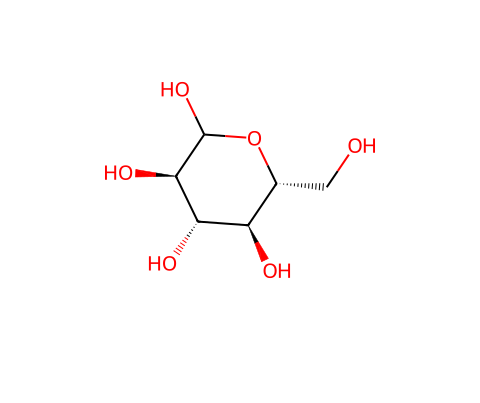

% Visualize D-Glucose
visualizeMolecule('C([C@@H]1[C@H]([C@@H]([C@H](C(O1)O)O)O)O)O', 'D_Glucose.png');

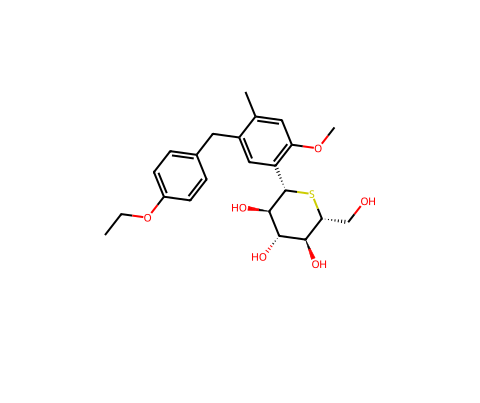

% Visualize Luseogliflozin
visualizeMolecule('CCOC1=CC=C(C=C1)CC2=CC(=C(C=C2C)OC)[C@H]3[C@@H]([C@H]([C@@H]([C@H](S3)CO)O)O)O', 'Luseogliflozin.png');

### Practical Perspective

Sodium-glucose co-transporter 2 (SGLT2) is a protein located in the kidneys responsible for reabsorbing glucose from the urine back into the bloodstream. D-Glucose, a naturally occurring monosaccharide, is reabsorbed via these SGLT2 transporters to help maintain normal blood glucose levels. In contrast, Luseogliflozin is a pharmaceutical SGLT2 inhibitor used to treat type 2 diabetes by blocking this reabsorption process. By inhibiting SGLT2, Luseogliflozin promotes glucose excretion in the urine, effectively lowering blood glucose levels and offering a therapeutic approach to managing hyperglycemia in diabetic patients.

The MATLAB Bioinformatics Toolbox enables visualization of the SGLT2 protein structure by simply inputting its PDB ID.

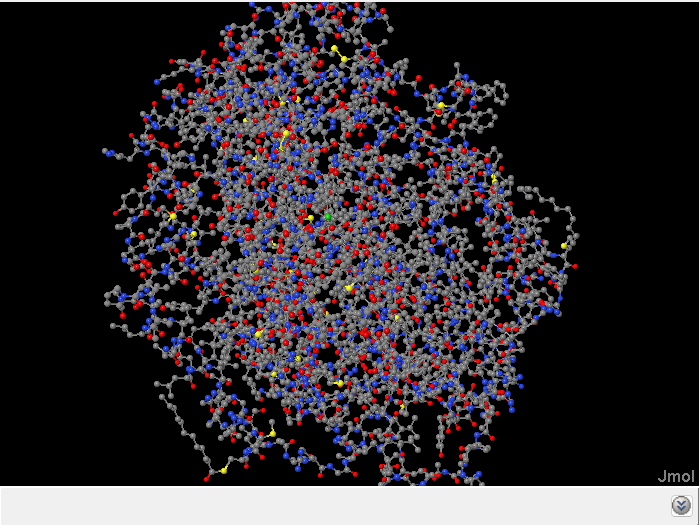

% Give PDB ID for SGLT2-Drug complex
pdbID = '7VSI';

% Use the molviewer (needs Bioinformatics toolbox) to visualize
molviewer(pdbID);

### Utility Function

function visualizeMolecule(smiles, filename)

    % Import RDKit libraries
    rdkit = py.importlib.import_module('rdkit');
    rdkitChem = py.importlib.import_module('rdkit.Chem');
    rdkitDraw = py.importlib.import_module('rdkit.Chem.Draw');

    % Create a molecule object from the SMILES string
    mol = rdkitChem.MolFromSmiles(smiles);

    % Generate a 2D depiction of the molecule and store in the specified file
    rdkitDraw.MolToFile(mol, filename);

    % Display the generated .png image
    rgbImage = imread(filename);
    imshow(rgbImage);
end


### Exercises

#### Ex. 1: Visually inspect the molecular structures 

Visually examine the molecular structures of D-Glucose and Luseogliflozin. Identify and describe the features in Luseogliflozin that resemble D-Glucose, allowing it to effectively bind to the SGLT2 transporters. 

#### Ex. 2: How can we quantify molecular similarity beyond visual inspection?

While visual inspection can reveal structural similarities between Luseogliflozin and D-Glucose, how might we quantify these similarities more rigorously? How can we automate the search for similar compounds in large databases. What metrics or algorithms can be used to quantify molecular similarity? Research learn about [Similarity Coefficients](https://chem.libretexts.org/Courses/Intercollegiate_Courses/Cheminformatics/06%3A_Molecular_Similarity/6.02%3A_Similarity_Coefficients).

#### Ex. 3: Think about how this simple exercise is used in drug discovery!

Imagine you are tasked with designing a new SGLT2 inhibitor. Think about how this exercise can help you to search for new potential drug candidates. Think about steps such as generating a molecular library, performing substructure searches, and using similarity indices to rank potential compounds.